Семинар 6.

## **Тема:** "Построение и анализ одномерного спектрального портрета"

**Задание:** Изобразить радиальный или линейный спектральный портрет произвольной матрицы, привести матрицу к клеточно-диагональному виду.

clc;
clear;
% Определяем размерность матрицы
n = 7; % Размер матрицы

% Генерируем произвольную матрицу
A = randn(n)

A =     0.2482   -1.5974   -0.0157   -0.5786    1.2400   -0.8738    0.0379
    0.5569   -1.4019   -0.7165    0.1971   -1.7651    0.0689    0.0315
    0.6431    0.3576    0.8672   -0.0410   -0.4110   -0.4251   -1.9026
    0.7391    0.3589   -1.5110   -1.5108   -0.3908   -0.1284    1.0208
   -1.3227    0.9246    0.8594    0.4848   -0.7137    1.9323    0.1545
   -0.6768    0.3656    0.4981    0.4426   -0.6639   -0.5419   -0.4340
   -0.3529   -0.7668    0.7731   -0.7431    0.4830    0.8855    0.0374


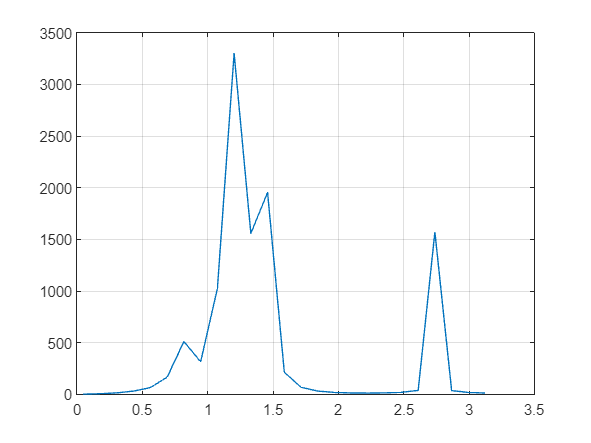


dist = sort(abs(eig(A)));
intervals = zeros(1, length(dist));
intervals(1) = dist(1);
for i = 2:length(dist)
    intervals(i) = dist(i) - dist(i - 1);
end

x_values = 0.05:min(nonzeros(intervals))/2:max(dist)+2*min(nonzeros(intervals));
y_values = zeros(1, length(x_values'));
for i = 1:length(x_values)
    y_values(i) = GetNormH((x_values(i)^-1).*A);
end
plot(x_values, y_values)
grid on;


rads = unique(dist);
for i = 1:length(rads)-1
    rads(i) = rads(i) + (rads(i + 1) - rads(i))/2;
end
rads(length(rads)) = rads(length(rads)) + min(nonzeros(intervals));
Projs = zeros(length(rads), n, n);
P1 = GetProjection((rads(1)^-1).*A);
for i = 1:n
    for j = 1:n
        Projs(1, i, j) = P1(i, j);
    end
end
for k = 2:length(rads)
    P2 = GetProjection((rads(k)^-1).*A);
    for i = 1:n
        for j = 1:n
            Projs(k, i, j) = P2(i, j) - P1(i, j);
        end
    end
    P1 = P2;
end
squeeze(Projs(length(rads),:,:))

ans =     0.4281   -0.2255   -0.3881   -0.0834   -0.0596   -0.5075   -0.0224
   -0.0749    0.2543    0.1550    0.1263   -0.4462    0.0754   -0.2626
   -0.2913    0.0885    0.2377    0.0230    0.1785    0.3493    0.0958
    0.1528    0.1120   -0.0605    0.0703   -0.4304   -0.1932   -0.2469
   -0.2114   -0.1180    0.0987   -0.0780    0.5168    0.2649    0.2956
   -0.2392    0.0833    0.1995    0.0244    0.1239    0.2862    0.0654
    0.2826   -0.3273   -0.3284   -0.1478    0.3398   -0.3239    0.2065


dims = zeros(1, length(rads));
for k = 1:length(rads)
    dims(k) = real(trace(squeeze(Projs(k,:,:))));
end

U = zeros(length(rads), n, n);
for k = 1:length(rads)
    [Uk,~,~] = svd(squeeze(Projs(k,:,:)));
    for i = 1:n
        for j = 1:n
            U(k, i, j) = Uk(i, j);
        end
    end
end

T = [];
for k = 1:length(dims)
    columns = squeeze(U(k,1:n,1:round(dims(k))));
    [a, b] = size(columns);
    if a < b
        columns = columns';
    end
    T = horzcat(T, columns);
end

D = inv(T)*A*T

D =    -0.6851   -1.5235    0.0000   -0.0000   -0.0000   -0.0000    0.0000
    0.7784    0.8271    0.0000   -0.0000    0.0000    0.0000         0
    0.0000    0.0000   -1.3971    1.0411    0.0000    0.0000   -0.0000
    0.0000    0.0000   -0.1964   -0.8289    0.0000    0.0000   -0.0000
   -0.0000   -0.0000   -0.0000   -0.0000   -1.4234   -0.0000   -0.0000
    0.0000    0.0000    0.0000   -0.0000    0.0000    0.6036   -2.8582
    0.0000    0.0000   -0.0000    0.0000   -0.0000    2.6421   -0.1117


function [mP, norm_H] = Dichotomy(X)
    A0 = X;
    epsn = 10^-5;
    [n, ~] = size(X);
    B0 = eye(n);
    H1 = inv(A0 - B0) * (A0 * A0' + B0 * B0') * inv((A0 - B0)');
    H0 = zeros(n, n);
    while norm(H0 - H1) > epsn * norm(H1)
        H0 = H1;
        V0 = inv(A0 + B0) * A0;
        U0 = eye(n) - V0;

        H1 = U0 * H0 * U0' + V0 * H0 * V0';

        F = [-B0 A0 zeros(n); A0 zeros(n) -B0];

        [~, R] = qr(F);
        A0 = R(n+1:2*n, n+1:2*n);
        B0 = -R(n+1:2*n, 2*n+1:3*n);
    end

    mP = -inv(A0 - B0) * B0;
    norm_H = norm(H1);
end

function normH = GetNormH(X)
    [~, normH] = Dichotomy(X);
end

function proj = GetProjection(X)
    [proj, ~] = Dichotomy(X);
end